### **Universidade Federal de Campina Grande**

### **Centro de Engenharia Elétrica e Informática**

### **Programa de Pós-Graduação em Engenharia Elétrica**

### **Análise e Projeto de Sistemas de Controle - 21.1**

### **Professor: Antonio Marcus Nogueira Lima**

### **Aluno: Arthur Dimitri Brito Oliveira **

### Campina Grande - 19 de Abril de 2021

### **Relatório - Atividade I**

## **Introdução **

    O Controle de sistemas consiste em utilizar ferramentas eletrônicas e/ou computacionais como controladores, de tal modo que um dado sistema comporte-se da maneira desejada. De acordo com a dinâmica deste sistema, uma abordagem de controle é aplicada, adequando a resposta temporal a um determinado gabarito temporal.

    Tradicionalmente, utiliza-se controladores lineares, para os quais realiza-se um ajuste dos ganhos proporcional, integral ou derivativo. O controlador sintonizado é concatenado à malha do sistema e, mediante interação com o mesmo, produz o comportamento desejado, ainda que sob perturbações. Muito embora tal estratégia de controle seja amplamente utilizada, em alguns processos ela pode não ser adequada. 

     Quando há variações no processo, a depender de algumas especificações, o controle adaptativo pode ser viável. Um controlador adaptativo pode ser definido como um controlador onde há um mecanismo de ajuste dos parâmetros. Sua estrutura básica pode ser visualizada na Figura xxxx. 

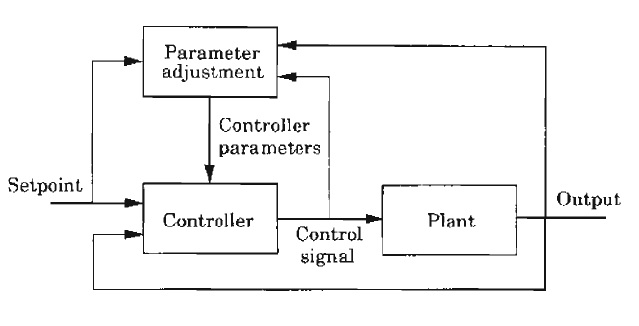

**Figura: **Diagrama de blocos de um sistema adaptativo.

    Como pode-se observar na figura acima, o diagrama possui duas malhas. A inferior é uma malha comum de realimentação. Pode estar associada a um problema clássico de controle, seja ele rastreio $Y(s)/R(s)$, esforço de controle $U(s)/R(s)
$ ou imunidade a perturbações. Estes tipos de problema apontam para uma classe de controladores plausíveis.

    A malha superior, por sua vez, é utilizada para ajustar o controlador em termos das variações do sistema. Normalmente, tem velocidade inferior à malha de realimentação. Se a referência $R(s)$ não muda, mas o processo $H(s)$ muda, os parâmetros do controlador precisam ser modificados. Ou seja, o processo pode variar, mas o rastreio $Y/R$ não pode. Naturalmente, a solução do problema de controle adaptativo implica em uma complexidade analítica maior. 

    Grande parte das variações em processos industriais é complexa e pouco compreendida. É possível que as causas da variação no processo não possam ser investigadas ou que tal investigação seja economicamente inviável. Controladores adaptativos podem ser úteis nesse contexto, e o conhecimento prévio do domínio do problema pode ser útil para estimar somente a parte desconhecida do processo. 

    Pode-se citar quatro tipos principais de sistemas adaptativos: escalonamento de ganho, MRAS (model-reference adaptative control), STR (self-tuning regulators) e controle dual. 

    Nos casos onde é possível identificar variáveis que tem uma forte correlação com a mudança de dinâmica no processo, o escalonamento de ganho é utlizado. O diagrama representativo deste método pode ser visualizado na Figura xxx.

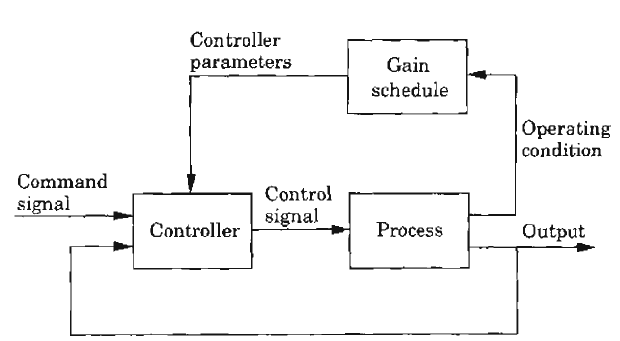

**Figura: **Diagrama de blocos - escalonamento de ganho

    Os parâmetros do controlador são atualizados pela malha superior.  Este ajuste normalmente é feito utilizando um conjunto de valores pré-definidos para determindas variáveis. Caso as variações ocorram de forma imprevisível, não é possível utilizar o escalonamento de ganho, sendo necessária a utilização de outra técnica de controle adaptativo. 

    O MRAS (Model-Reference Adaptative System) determina como a saída do processo deveria responder ao sinal de controle. Um diagrama deste método pode ser observado na Figura 1.

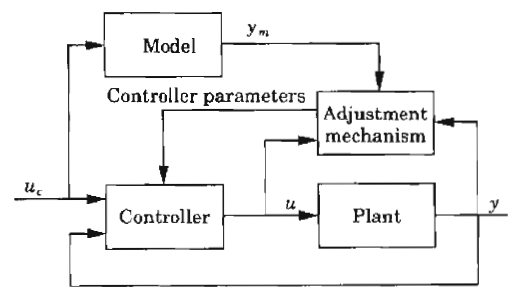

**Figura 1: **Diagrama de blocos - MRAS

    A malha interna de controle é uma malha comum de realimentação composta pelo processo e pelo controlador. A malha mais externa ajusta os parâmetros do controlador de tal forma que o erro entre a saída do sistema e a saída do modelo seja minimizado. Ou seja, o objetivo principal com o MRAS é determinar o mecanismo de ajuste para o qual um sistema estável, que torne o erro nulo, seja obtido. 

    O controle adaptativo utilizando STR (self-tuning regulators) consiste em um método indireto, visto que não há regras que determinam, diretamente, como os parâmetros do controlador devem ser ajustados.  O diagrama de blocos desse método pode ser visualizado na Figura 2. 

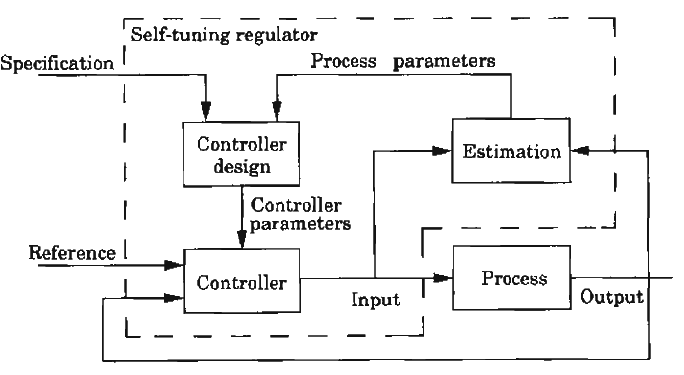

**Figura 2: **Digrama de blocos - STR

    O ajuste de parâmetros é feito pela malha mais externa do diagrama. Nela há um estimador recursivo de parâmetros. O sistema pode ser visto como uma automação do processo de modelagem e controle, no qual o modelo do processo e o projeto são atualizados a cada instante de tempo. Sendo assim, o controlador STR automaticamente sintoniza os seus parâmetros para obter as propriedades desejadas em malha fechada. 

    Diante das técnicas introduzidas nesta seção, o objetivo deste relatório é descrever a utilização de algumas delas para a resolução dos exercícios propostos no Capítulo 1 do Livro.

## **Resoluções **

    Para a resolução dos problemas aqui listados, utilizou-se o Simulink e *scripts *Matlab. A teoria que fundamenta as resoluções é apresentada na Introdução deste documento. Inicialmente, os resultados presentes nos exercícios resolvidos foram replicados. Posteriormente, foram detalhadas as resoluções das questões propostas. 

## **Exercícios Resolvidos**

**Questão 1 - Diferentes respostas em malha aberta**

*    O objetivo nesta questão consiste em avaliar como a mudança dos parâmetros tem efeito sobre o sistema em malha aberta e pouco em malha fechada. *$a = -0.01, 0, 0.01$


$$$G_o(s) = \frac{1}{(s+1)(s+\alpha)}$$$


Pela resposta em malha aberta para o polo variando proximo de 0, observa-se que o sistema atinge a estabilidade somente com a=0.01. No caso de a=0, o integrador, e a=-0.01, o sistema é instável.

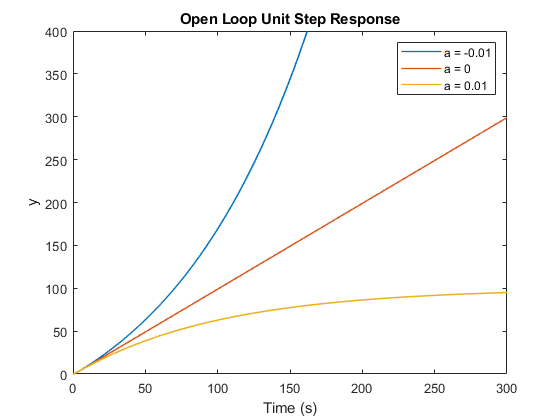

q1_1

**Figura **: Resposta ao degrau em malha aberta do sistema com variação do parâmetro a.

    Em malha fechada, o comportamento dos 3 sistemas possíveis é similar. Observa-se que uma lei de controle proporcional unitária é capaz de conduzir o sistema à estabilidade, mostrando que o controlador não é sensível à variação do polo em malha fechada. 

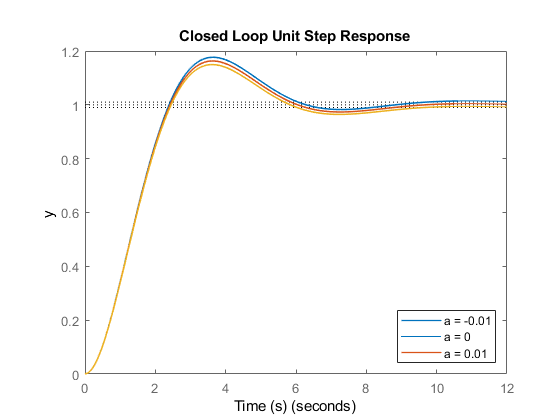

q1_2

**Figura **: Resposta ao degrau em malha fechada do sistema com variação do parâmetro a.

    Pelo diagrama de bode, pode-se observar que, em malha aberta, os sistemas diferem em baixas frequências e apresentam comportamento similar em altas frequências. Em termos do ganho, não importa se o parâmetro $\alpha > 0$ ou $\alpha < 0$, em baixas e altas frequências a magnitude a variação de magnitude é a mesa para os três casos. No entanto, para baixas frequências no caso de $\alpha = 0$ a magnitude permanece constante até aproximadamente $10^{-2} rad/s$. 

    No que diz respeito à fase, o valor de $\alpha$ para cada um dos casos é capaz e provocar comportamentos distintos. A fase difere em baixas frequências para os três casos e é virtualmente idêntica em altas frequências.

    A partir disso, é possível afirmar que o controlador projetado operará de forma satisfatória para todas as possíveis configurações do sistema, contanto que garanta-se que a largura de banda do controlador seja suficientemente alta. 

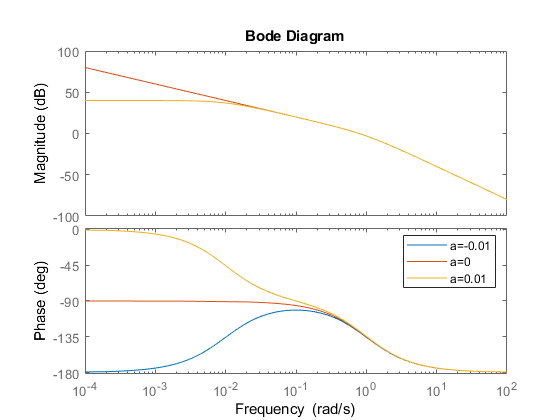

q1_3

**Figura **: Resposta em frequência do sistema em malha aberta

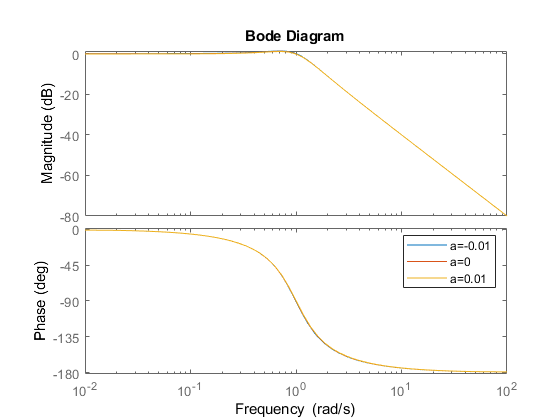

q1_4

**Figura **: Resposta em frequência do sistema em malha fechada

**Questão 2 - Respostas em malha aberta semelhantes**

Considerando o processo descrito por:


$$G_0(s) = \frac{400(1 - sT)}{(s+1)(s+2)(1 + Ts)} $$


Pelo teorema do valor final, o processo, em malha aberta:

 
$$\lim_{t \to \infty} G_o(t) = \lim_{t \to 0}  G_o(s) = \frac{400}{20} = 20$$


Ou seja, em malha aberta, o sistema atinge o regime para quaisquer valores possíveis de T. Isto se confirma pela resposta em malha aberta do sistema, onde há uma similariade considerável entre as respostas. 

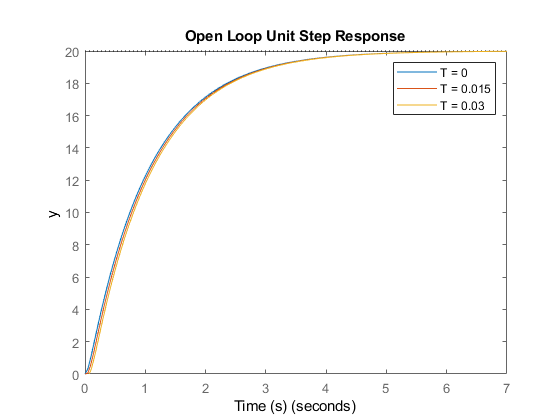

q2_1

**Figura **: Resposta ao degrau em malha aberta do sistema.

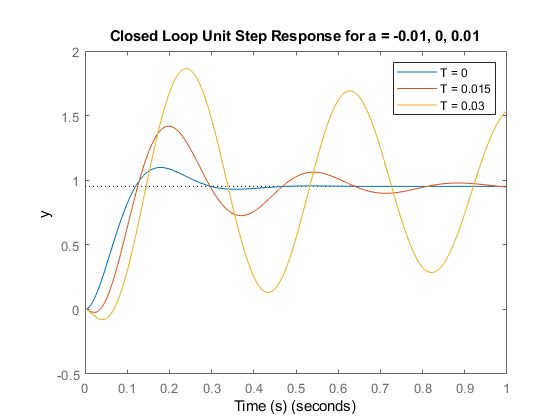

q2_2

**Figura **: Resposta ao degrau em malha fechada do sistema.

**Questão 3 - Integrador com Sinal Desconhecido**

Dado um processo descrito por:


$$G_o(s) = \frac{kp}{s}$$


    O sinal de kp pode assumir valores positivos e negativos. Tendo um controlador descrito por $S(s)/R(s)
$, e assumindo que $deg R \ge deg S$, o polinômio característico do sistema em malha fechada é $P(s) = sR(s) + kpS(s)$. Assumindo $R(s) = s + \alpha$ e $S(s) = \beta$, tem-se:


$$$ P(s) = s^2 + \alpha S + \beta Kp $$$



$$s = \frac{-\alpha \pm \sqrt{\alpha^2 -4\beta kp}}{2}$$


    Como pode-se observar, caso $kp <0$,  $\sqrt{\alpha^2 -4\beta kp} > \alpha
$, o que implica em um pólo no semiplano direito.O polinômio característico sempre poderá ter uma raíz no semiplano direito.

**Questão 4 - Válvula Não-Linear **

Na questão há uma válvula com comportamento não linear, com função característica na forma:

$f(u) = u^4$, $u \ge 0$

A planta é descrita pela seguinte função de transferência:


$$G_o(s) = \frac{1}{(s+1)^3}$$


    O sistema tem um comportamento satisfatório para alguns valores de operação, mas para outros o sistema em malha fechada torna-se instável, como pode-se observar na Figura xxxx, onde o ponto de operação é gradualmente incrementado.

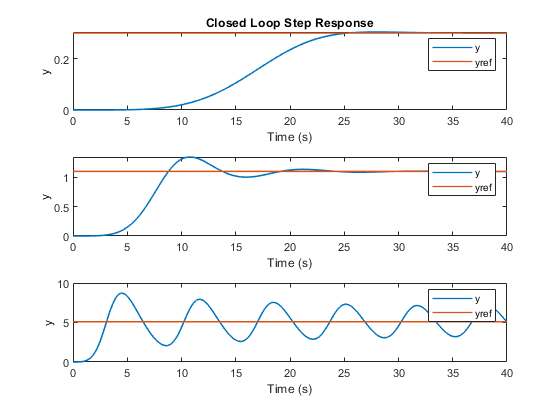

ex_1_4

**Figura **: Output concentration response for different flows.

    O que acontece é que, à medida que a magnitude do sinal de controle aumenta, o sinal de saída da válvula também aumenta, na forma de potência de quatro.  Uma solução possível é passar o sinal de controle por uma inversa da função não linear, que pode ser modelada por funções lineares. Assim, garante-se uma região de operação da válvula que não conduz a instabilidades do sistema em malha fechada.


$$v = f(u) = f(f^{-1}(c))$$


    A curva que descreve o comportamento da válvula e as funções lineares utilizadas para a aproximação podem ser visualizadas na Figura xxx. 

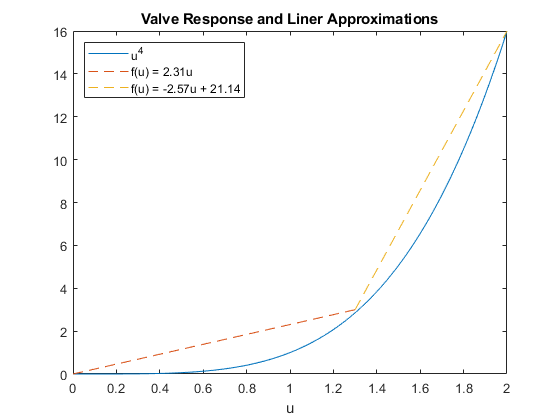

ex_1_4_linearization_curve

**Figura:** Comportamento da válvula e funções lineares utilizadas para aproximação. 

    Um novo experimento, incorporando o bloco de inversão antes do bloco da planta foi realizado. Como pode-se observar na Figura xxx, há uma melhoria considerável no desempenho do sistema em malha fechada, especialmente para sinais de referência de maior magnitude. Mediante uma melhor modelagem da função inversa, é possível tornar o processo ainda mais insensível à não linearidade da válvula. 

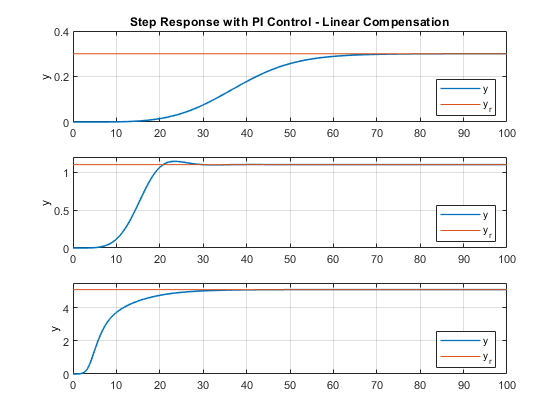

ex_1_4_linearized

**Figura: **Resposta ao degrau do sistema utilizando a compensação por aproximação linear da válvula. 

**Questão 5**

A questão descreve um problema de controle de concentração de um líquido que flui por meio de um cano até um tanque. A equação diferencial que descreve o sistema é:


$$V_m \frac{dc(t)}{dt} = q(t)(c_{in}(t-\tau) - c(t))
$$


Onde $\tau = V_d/q(t)
$e $T = V_m/q(t)
$. $q
$ representa o fluxo. $cin $ é a concentração de entrada. $V_d $ é o volume do cano. $V_m$ é o volume do tanque. Para um fluxo fixo, a função de transferência do processo é dada por:


$$G_o(s) = \frac{e^{-s\tau}}{1 + sT}$$


Para um controlador PI com ganhos fixos, como pode-se observar na Figura xxx, há um *overshoot *inversamente proporcional ao fluxo. Especialmente para q = 0.5, a resposta do sistema excede quase 50% do valor desejado.

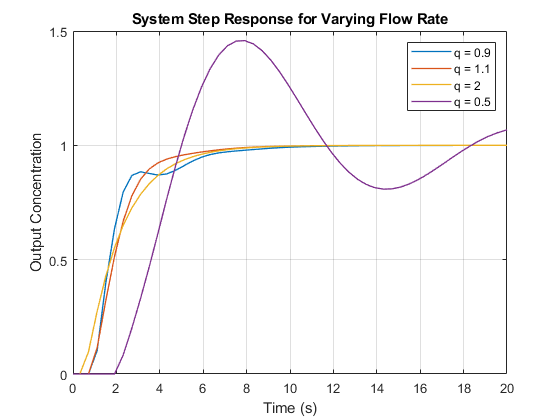

ex_1_5

**Figura: **Resposta ao degrau do sistema - fluxo variante.

Uma das maneiras de lidar com isto é projetar um controlador utilizando o método de Ziegler-Nichols. Para um controlador PI, na forma $K(1 + \frac{1}{T_i}s)$, considerando os parâmetros do problema, os ganhos são:


$$K = \frac{0.9T}{\tau} = \frac{0.9Vm}{Vd}$$



$$T_i = 0.3\tau = 0.3\frac{Vd}{q}$$


Assim, o ganho proporcional é fixo e o ganho integral varia de acordo com a variação do fluxo. A resposta do sistema com o novo controlador pode ser observada na Figura xxx. 

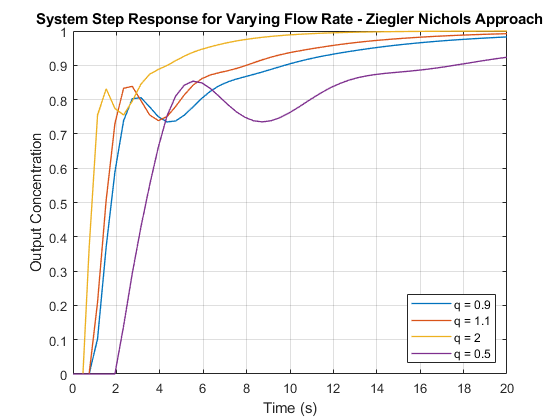

ex_1_5_zn

**Figura: **Respostas ao degrau com fluxo variante. 

    Pode-se afirmar que o controlador dependente dos parâmetros de operação do sistema é capaz de levar o sistema ao ponto de operação desejado com menor sobressinal quando comparado ao controlador de ganhos fixos. No entanto, observa-se que para o caso mais crítico do controlador anterior, quando q = 0.5, o sistema leva mais tempo para alcançar o ponto de operação desejado. E isto é natural, visto que a ação integral do controlador é proporcional ao fluxo. 

**Questão 6 - Controle de uma aeronave**

O modelo de uma aeronave pode ser expresso, assumindo a aeronave um corpo rígido, por:

    Onde $N_z
$ representa a aceleração normal, $\dot{\theta}
$ a taxa de *pitch, *e $\delta_e$ o ângulo de elevação. Os parâmetros do modelo dependem das condições de operação do sistema, que podem ser descritas em termos do número de Mach.

    O sistema tem três autovalores. Dois deles dependem das condições de vôo, as quais podem ser determinadas a partir do número de Mach e da altitude. O objetivo do exemplo é demonstrar que o sistema é instável para condições de vôo subsônicas (FC = 1, 2 e 3) e instável para a condição supersônica. 

    Mediante o fornecimento dos espaçoes de estados possíveis para cada uma das condições de vôo, simulou-se a resposta do sistema ao degrau, tendo um mesmo controlador proporcional de ganho unitário atuante. O resultado pode ser observado na Figura xxx.

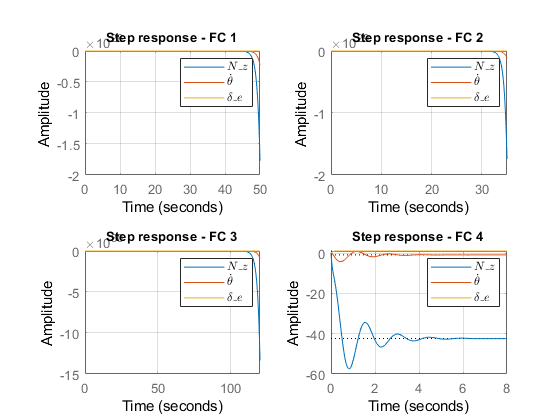

ex_1_6

**Figura: **Resposta ao degrau para o sistema descrito com $K_p = 1$

    Fica claro que o sistema é instável para as condições de vôo 1 a 3, ou seja, para condições subsônicas. Para a condição de vôo 4, o sistema se comporta de forma estável. No entanto, apresenta uma resposta pouco amortecida, especialmente para os estados $N_z$ e $\dot{\theta}$. Pelos resultados, pode-se afirmar que, devido às variações associadas às condições de vôo, não é possível utilizar um controlador com os mesmos parâmetros para todas elas. A solução para este tipo de problema é utilizar um controlador adaptativo que leve em consideração as variações de altitude e número de Mach.

    Como propõe a seção 9.5 DO LIVRO XXX, mediante realimentação dos estados anteriormente mecionados, tem-se três variáveis para escalonar: a altura H, a velocidade aérea indicada $V_{IAS}
$ e o número de Mach $M
$.Os parâmetros do controlador, para o ângulo de pitch, podem ser expressos por:


$$K_{QD} = K_{QD_{IAS}} + (K_{QD_H} - K_{QD_{IAS}})MF$$



$$MF = \frac{1}{s + 1}K_{MF}$$


Tais parâmetros variam conforme a velocidade aérea indicada e conforme a altitude.

**Questões 7 e 8**

    Problemas onde há variações significativas nas características da perturbação, especialmente quando estas agem na entrada do processo, podem ser solucionados por meio da sintonia do controlador à característica da perturbação. Se as perturbações têm alguma regularidade estatística, é possível alcançar uma melhoria significativa no controlador ao sintonizá-lo a uma característica particular da perturbação. 

    No caso de uma navio, há a necessidade de compensar as forças de perturbação que atuam nele por conta do vento, ondas e a correnteza. As ondas têm componentes periodicas intensas. A frequências das forças geradas pelas ondas varia muito por conta da velocidade e da direção do navio. Neste caso, faz-se necessário levar em conta a natureza variante da perturbação das ondas ao projetar um controlador que lide com tais características.

    Considerando um processo descrito por  $\frac{1}{s+1}$, simula-se uma perturbação, na forma de ruído branco, que passa por um filtro passa-banda e é adicionada à malha fechada como uma perturbação. O objetivo é mostrar que quando o controlador é sintonizado para a frequência central $w_c = w$ utilizada para gerar a perturbação, há uma rejeição significativa do ruído utilizado como perturbação. O diagrama da estratégia descrita pode ser observado na Figura XX.

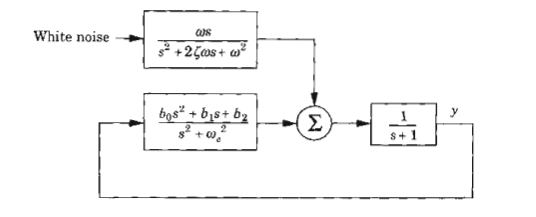

**Figura: **Diagrama do sistema com perturbações.

    O sistema foi simulado para as condições: $w = w_c$, $w > w_c$ . Os resultados podem ser observados na Figura XX. 

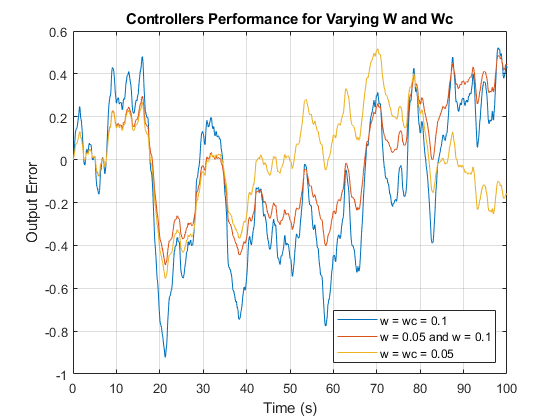

Ex_1_8_plot

**Figura: **Desempenho dos controladores em termos do erro para w e wc variantes.

    Como pode-se observar, não foi possível replicar no experimento o resultado esperado. Para os casos onde $w = w_c$, esperava-se um erro menor na saída, visto que o ganho do controlador na frequência central da perturbação é maior. Enquanto que, para $w \neq w_c$, era esperada uma piora no desempenho do controlador. Esta diferença pode ser atribuída a problemas na simulação, como a integração do sinal de perturbação. 

**Questões 9 e 10**

    Considerando um sistema SISO, de única entrada e única saída, e assumindo sua ordem como $n
$, o controlador pode ser parametrizado pelos elementos da matriz L. 


$$u = -Lx$$


Um controlador linear tem sua função de transferência descrita por:


$$R(s)U(s) = -S(s)Y(s) + T(s)U_c(s)$$


R,S,T são polinônios e U, Y e Uc são os sinais de controle, saída do processo e o sinal de referência do sistema. 

**Questões 11, 12 e 13**

    No controle adaptativo indireto, alvo desta seção, o modelo do processo e possivelmente as características da perturbação são primeiramente determinadas. O atrito, por exemplo, é comum a sistemas mecânicos. Para um sistema de controle de um motor, o atrito é uma perturbação que pode ser compensada ao adicionar um sinal ao controlador, da forma:

    Neste sinal, leva-se em consideração a velocidade $v
$ do motor. O motivo de ter duas funções se dá pelo fato de que as forças de atrito não são simétricas. Quando a velocidade é positiva, adiciona-se um sinal de controle positivo $u_{+}$, e quando é negativa, adiciona-se um sinal $u_{-}$. Há muitos fatores envolvidos na força de atrito. Por isso, pode-se utilizar um mecanismo para ajuste dos sinais de controle, por meio de aprendizagem de máquina por exemplo. 

    Na época em que o livro foi escrito, já se falava que os controladores já tinham a introdução de alguma forma de adaptação, especialmente em sistemas distribuidos. E isso se dá especialmente devido ao desempenho superior de abordagens adaptativas quando comparadas a controladores mais genéricos, visto que os controladores adaptativos podem levar em consideração mudanças no processo e lidar com perturbações determinísticas ou não.

    No caso do piloto automático utilizado em aeronaves, a abordagem adaptativa é preferível à convencional, pois resulta em um melhor desempenho e é mais fácil de operar. E isso pode ser atribuído à lei de controle mais complexa, que tem oito parâmetros ao invés do controlador tradicional, além de um modelo interno de movimento. 

## **Problemas Propostos**

**Questão 1 - Busque por definições de "adaptativo" e "aprendizado" e a utlização destas palavras em diferentes áreas**

    Adaptativo está relacionado à capacidade de adaptação de algo, à sua adaptabilidade. O dicionário Aurélio define “adaptabilidade” como a qualidade ou capacidade do que é adaptável, e define adaptável como alguma entidade que pode ser mudada, em alguma das suas caraterísticas, com a finalidade de ajustá-la para uma nova situação. No ramo da Biologia, está associada à capacidade de um indivíduo se adequar a mudanças no meio ambiente que o cerca. No contexto de Engenharia de Controle, está associada a sistemas cuja lei de controle se ajusta a mudanças no processo, por exemplo. 

    Aprendizagem, Aprendizado é a ação, processo, efeito ou consequência de aprender. .A duração do processo de aprender; o tempo que se leva para aprender.O exercício inicial sobre aquilo que se conseguiu aprender; experiência ou prática. No contexto de aprendizagem de máquina, refere-se ao processo em que minimiza-se uma função de custo de modo a produzir a saída desejada a partir de entradas exemplo. Na área de controle, pode estar associada a encontrar uma solução ótima para os sinais de controle necessários para produzir uma resposta temporal desejada, de forma generalizada, para um domínio de problema comum.

**Questão 2 - Encontre descrições de controladores adaptativos de alguns fabricantes**

    A Ford utiliza uma ferramenta de controle adaptativo denominada *Ford Load Adaptive Control [xxxxxxxxx]. *Ela é utilizada para ajustar o controle de estabilidade eletrônica de acordo com a carga total que o veículo carrega. Por meio de sensores inteligentes, o peso e a posição do veículo são calculados Este tipo de controle é essencial, visto que garante a estabilidade e segurança do veículo caso ele esteja vazio ou carregado.

    A NASA desenvolveu, em 2011, controladores adaptativos para a aeronave F-18 [xxxx]. Um deles, o "onMRAC" (OCM + normalization model-reference adaptive control), é baseado na lei de modificação adaptativa de controle ótima (OCM). Utiliza-se também uma abordagem envolvendo normalização, que é utilizada para evitar adaptações excessivas devido a entradas de excitação excessivas. Um variante deste, o “onMRAC+" inclui uma lei de controle adaptativa aicional que lida com falhas que resultem em incertezas que não possam ser completamente canceladas por meio da ação de realimentação.

**Questão 3 - Elenque situações nas quais o controle adaptativo pode ser útil. Que fatores você consideraria ao julgar a necessidade de um controle adaptativo?**

    A diferença chave entre controladores adaptativos e controladores lineares é a habilidade que os controladores adaptativos tem de lidar com incertezas e se autoajustar. Especialmente nestas situações, o controle adaptativo pode ser extremamente útil. Para analisar a viabilidade e necessidade de sua aplicação, é necessário avaliar o processo e no que consistem as incertezas associadas. 

    Primeiramente, analisa-se o processo e a natureza de sua dinâmica: constante ou variável. Caso sua dinâmica varie ao longo do tempo, é recomendável a utilização de um controlador com parâmetros variantes. Posteriormente, deve-se analisar se tais variações são previsíveis ou não. Caso sejam previsíveis, basta utilizar um esquema de escalonamento de ganho. Se forem imprevisíveis, o mais recomendado é utilizar um controlador adaptativo. 

    A utilização do controle adaptativo pode necessitar de técnicas mais simples ou mais complexas, a depender dos fatores relacionados a mudança no processo. Isto pode partir de um simples escalonamento de ganho a um STR (self-tuning regulator), onde os parâmetros são autoajustáveis para quaisquer variações no processo.

**Questão 5 - **

    O sistema é o mesmo do Exemplo 4, com as seguintes características:


$$G_o(s) = \frac{1}{(s+1)^3}$$



$$f(u) = u^4$$


    O objetivo é determinar as raízes da equação característica em malha fechada. Definindo o controlador PI com $k = 0.15
$ e $T_i = 1$, tem-se as seguintes raízes

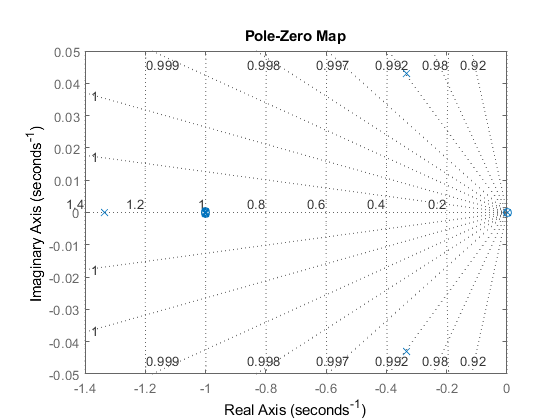

questao_1_5

**Figura: **Localização das raízes no plano complexo

    Observando a Figura acima, contata-se que todas as raízes da equação característica em malha fechada estão localizadas no semiplano complexo esquerdo. Sendo assim, pode-se afirmar que o sistema é estável. Quanto à estabilidade para os valores de referência impostos, como descrito no Exemplo 4, para Cr=5 o sistema torna-se instável, o que mostra que o controlador PI tradicional não é suficiente para levar o sistema à estabilidade. 

**Questão 6 **

A questão consiste no mesmo problema do exemplo 5. Assume-se que os volumes do cano e do tanque são unitários $V_m = V_d = 1$, e que o fluxo nominal é $q = 1
$. O processo pode ser descrito por:


$$G_o(s) = \frac{e^{st}}{1 + sT}$$


Por meio da formulação de Ziegler Nichols, tem-se que os ganhos proporcional e integral são:

$K_c = \frac{0.9T}{\tau} = 0.9$ e $T_i = 0.3\tau = \frac{0.3}{q}$

    Aplicando o controlador projetado em malha fechada, tem o desempenho ilustrado na Figura xxx. 

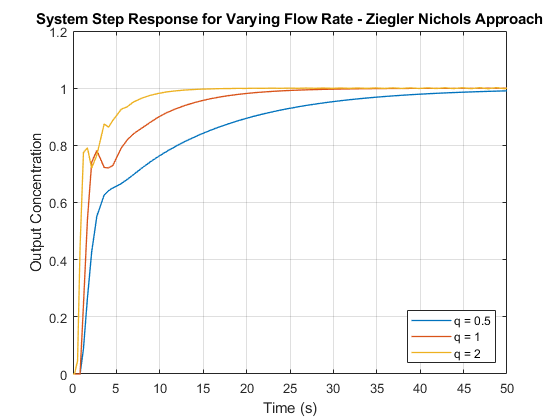

q_1_6

**Figura: **Resposta ao degrau do sistema - abordagem utilizando Ziegler-Nichols

    Fica evidente que o controlador consegue estabilizar o sistema em malha fechada. O sistema com $q=2$ atinge a referência em um menor tempo de simulação, enquanto que à medida que o fluxo descresce, o sistema leva mais tempo para alcançar a referência desejada. E isso pode ser explicado por meio do equacionamento dos ganhos. 

    Enquanto que o ganho proporcional é fixo $Kp = 0.9
$, o ganho integral é dado por $K_i = \frac{K}{Ti} = \frac{K}{\frac{0.3}{q}}= \frac{qK}{0.3}$. Ou seja, quanto menor é o fluxo, menor é a ação integral do controlador. Como não há requisitos adicionais quanto ao gabarito temporal, pode-se considerar que o controlador alcança o desempenho desejado. Vale-se salientar que o melhor desempenho do controlador é alcançado quando este é projetado de acordo com o processo nas condições operantes. Ao utilizar este mesmo controlador para condições de operação distintas, o comportamento pode não ser satisfatório. 

**Questão 7**

O espaço de estados de um sistema de duas entradas e duas saías é descrito por:

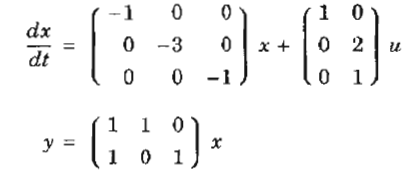

À segunda malha, adiciona-se uma realimentação proporcional. A função de transferência de $u_1$ para $y_1$ é expressa por: 

    syms k_2 s
 A = [-1 0 0;0 -3 0;0 0 -1]-[0;2;1]*[1 0 1]*k_2;
 B = [1;0;0];
 C = [1 1 0; 1 0 1];
 D = 0;
 phi = inv(s*eye(3)-A);
 H = C*phi*B+D;
 G = simplifyFraction(H);
 G(1)

$$ans = \frac{k_{2}+4\,s-k_{2}\,s+s^{2}+3}{\left(s+1\right)\,\left(s+3\right)\,\left(k_{2}+s+1\right)}$$

    Pela equação característica não expandida, observa-se que $k_2$ determina um dos polos do sistema em malha fechada. Avaliando sua influência na resposta temporal, para avaliar a resposta do sistema em regime permanente, tem-se que:


$$\lim_{t \to \infty} s\frac{k_2 + 4s - k_2s + s^2 + 3}{(s+1)(s+3)(k_2+s+1)}$$


    Inicialmente, pode-se observar somente quando $k_2 = -1$, o zero incorporado pelo TVF é cancelado com o pólo em zero e o sistema em regime permanente alcança valor final $2/3$. Quando $k_2 \neq -1$, o pólo não é cancelado e a resposta do sistema vai para zero. Sendo assim, $k_2$ influencia diretamente o erro em regime permanente de $y_1
$.

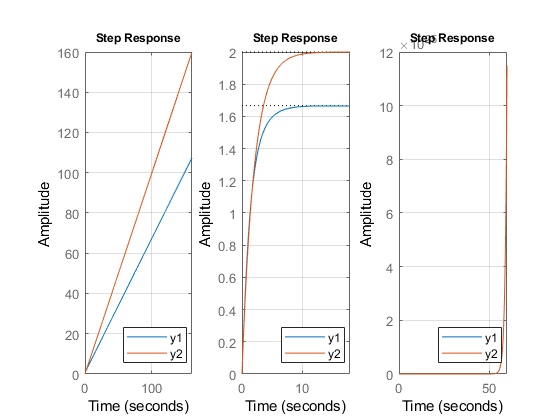

q_1_7

**Figura: **Resposta ao degrau em malha fechada para y1 e y1; k = -1, k = -0.5, k = -2

**Questão 8**

    Um sistema utilizado para corte de metal tem um sensor que mede a força aplicada e um controlador que ajusta a realimentação para manter a força de corte constante. A força de corte é dada aproximadamente por:


$$F = ka(\frac{v}{N})^\alpha$$


    Onde a é a profundidade do corte, $v
$ a taxa de alimentação, $N$a velocidade do eixo. O diagrama do sistema pode ser observado na Figura xx. 

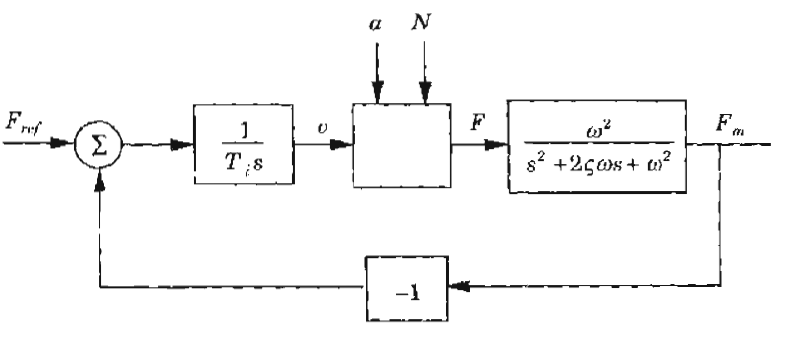

    O ganho de regime permanente é dado por:


$$K = k \alpha a v^{\alpha-1}N^{-\alpha}$$


    Assumindo $\alpha = 0.7
$, $k = 1$, $a = 1$, $\zeta = 0.7$ e $\omega = 5$. Para $T_i = 1$, variou-se o valor de $N$ entre 0.2 e 2, com $a = 1$. Posteriormente, variou-se $a$ entre 0.5 e 4. A resposta do sistema pode ser observada na Figura xxx. 

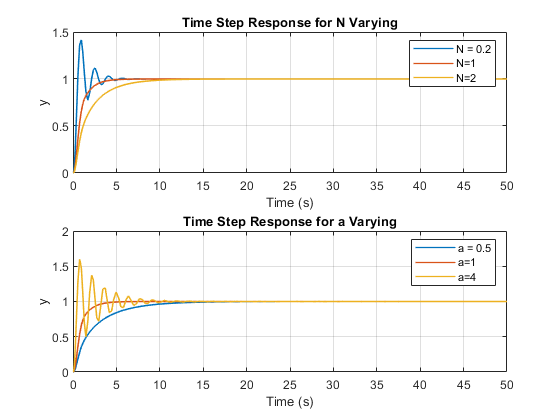

q_1_8

**Figura: **Resposta ao degrau - a e N variando.

**Questão 9**

Considerando um sistema do tipo:


$$G_o(s) = \frac{K}{s+a}$$


$K = K_o + \Delta K$, $K_o = 1$

$a = a_o + \Delta a$, $a_o = 1$


$$-0.5 \leq \Delta K \leq 2$$



$$-2 \leq \Delta a \leq 2$$


    Pelo fato de $a < 0$ para $\Delta a < - 1$ (sistema instável), considerou-se o intervalo $0 \leq a \leq 3$ e $0.5 \leq K \leq 3$.  Realizando a simulação de todas as combinações possíveis de $a$ e $K$, obteve-se as respostas ao degrau visualizadas na Figura xx.

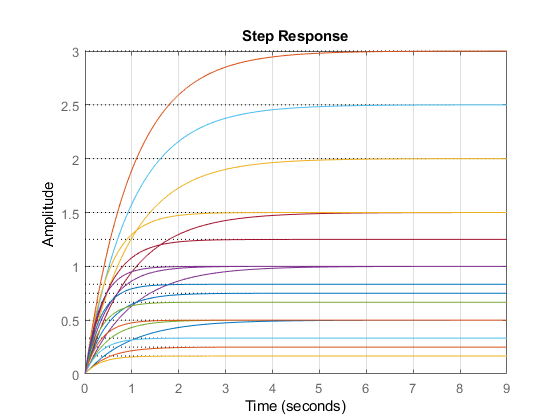

q_9_parte_1

**Figura: **Resposta ao degrau em malha aberta - K e a variantes

    Considerando agora a condição nominal de operação, a função de transferência em malha fechada, com um controlador proporcional de ganho unitário, torna-se:


$$G_{c} = \frac{\frac{K_o}{s+a_o}}{1 + \frac{K_o}{s+a_o}} = \frac{K_o}{s + a_o + K_o} = \frac{1}{s+2}$$


Avaliando a resposta ao degrau do sistema, em malha fechada, tem-se:

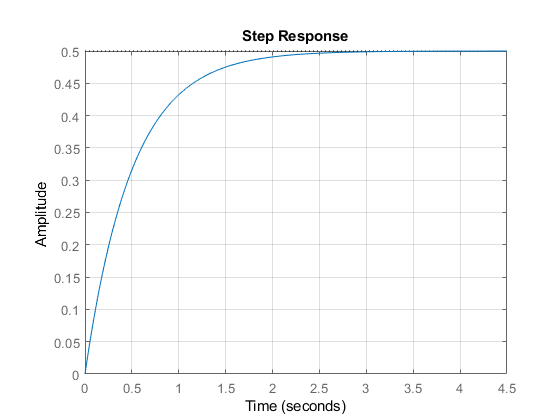

step(tf([1],[1 2])); grid 

**Figure: **Resposta ao degrau do sistema em malha fechada com controlador proporcional de ganho unitário.

    Muito embora o sistema seja estável, em malha fechada, para a condição nominal, os polos tem influência tanto de $a$ quanto de $k$, basta que as seguintes condições sejam satisfeitas para que o sistema tenha um pólo no semiplano direito. 

$k < a$, $a < k
$ ou $a < 0; k <0$

    Sendo assim, é necessário um controlador com ação integral. Em malha fechada, tem-se que:


$$Y = (U_c - Y)[\frac{1}{s}(\frac{k}{s+a})]$$



$$Y(1 + \frac{k}{s^2 + as})= U_c(\frac{k}{s^2+as})$$



$$\frac{Y(s)}{U_c(s)} = \frac{K}{s^2+as+k}$$


    Sendo assim, a partir da equação característica, tem-se:


$$s = \frac{-a \pm \sqrt{a^2-4k}}{2}$$


    Ou seja, pode-se afirmar que o controlador com ação integral unitária é capaz de alocar todos os pólos do sistema no semiplano esquerdo para quaisquer valores de $\Delta a$ e $\Delta k$.

    Para avaliar a sensibilidade a uma perturbação, d(t) é definida como: 

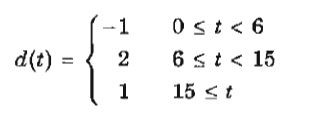

Aplicando tal perturbação ao sistema, para os dois controladores, tem-se:

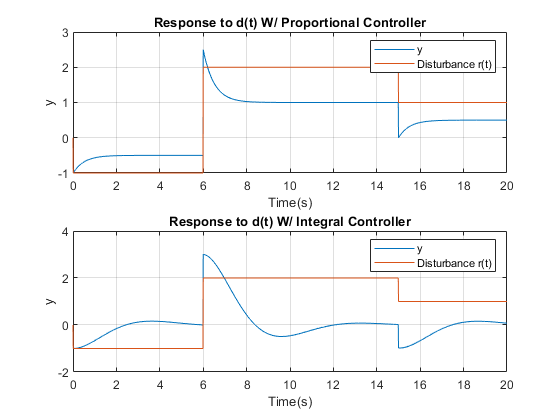

q_9_parte_2

**Figura: **Avaliação da resposta ao distúrbio do sistema com os controladores P e I. 

    O que pode-se observar é que, para os parâmetros nominais do sistema, o controlador proporcional de ganho unitário não é capaz de insensibilizar o sistema em malha fechada à perturbação aplicada. A resposta do sistema não acompanha a referência nula desejada. Para o controlador integral, no entanto, há a rejeição do distúrbio. 

    Para investigar a influencia de um erro de medição no sistema, adicionou-se um ruído branco ao sinal medido. Como requerido, utilizou-se o sistema com parâmetros nominais e um controlador integral. O resposta do sistema, considerando tal perturbação na medição, pode ser visulizada na Figura xxx.

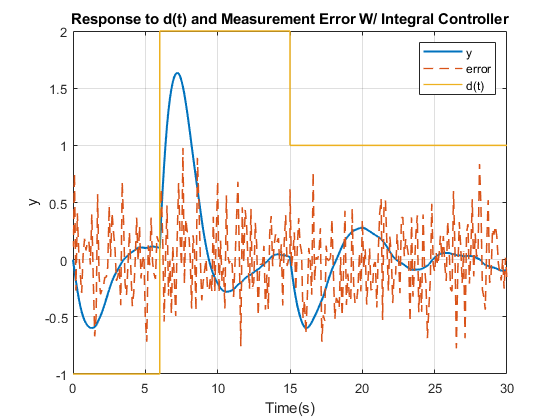

q_9_parte_3

**Figura: **Resposta ao degrau considerando um erro de medição - d(t) atuante e controlador I com ganho unitário.

    Observa-se que o controlador foi capaz de manter o sistema no ponto de operação desejado, apesar do erro adicionado à medição do estado. A saída oscila em torno de zero, com picos mais acentuados nas regiões de transição do sinal de perturbação $d(t)$. 

**Questão 10 **

    Dado um processo descrito por:


$$G_o(s) = \frac{K}{s^2 + a_1s + a_2}$$



$$K = K_o + \Delta K$$
      
$$K_o = 1$$



$$a_1 = a_{10} + \Delta a_1$$
    
$$a_{10} = 1.4$$



$$a_2 = a_{20} + \Delta a_2$$
    
$$a_{20} = 1$$



$$-0.5 \leq \Delta K \leq 2
$$



$$-2\leq \Delta K \leq 2
$$



$$-3 \leq \Delta K \leq 1
$$


    Para avaliar como a variação dos parâmetros descritos influencia a resposta temporal do sistema, simulou-se a resposta ao degrau para os sistemas possíveis. É importante salientar que a equação característica de $G_o(s)
$, diante da variação dos parâmetros $K$, $a_1$ e $a_2$, pode resultar em pólos instáveis. Por isso, na resposta ao degrau, levou-se em consideração somente a combinação de parâmetros que resulta em pólos no semiplano esquerdo. A resposta temporal pode ser observada na Figura XXX. 

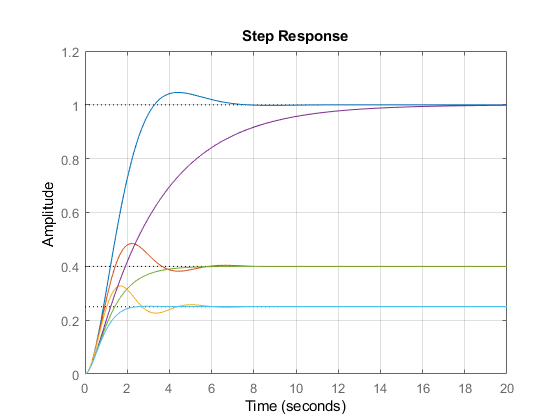

q_1_10_parte_1

**Figura: **Resposta ao degrau em malha aberta - Combinação de $K$, $a_{1}$ e $a_2
$ - pólos estáveis.

    A função de transferência em malha fechada do sistema, com um controlador proporcional de ganho unitário, para a condição nominal, é expressa por:


$$G_cl = \frac{G_o}{1+G-o} = \frac{\frac{K}{s^2 + a_1s + a_2}}{1 + \frac{K}{s^2 + a_1s + a_2}} = \frac{K}{s^2 + a_1s + a_2 + K} = \frac{1}{s^2 + 1.4s +2}$$


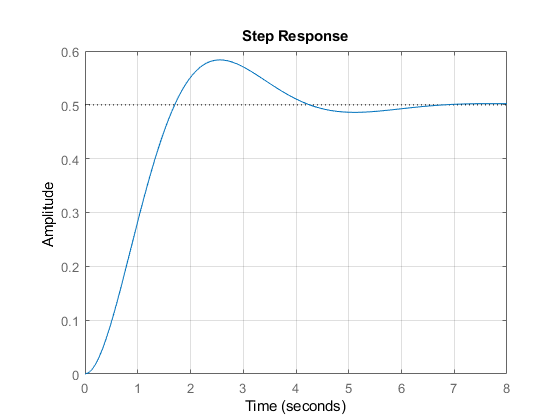

q_1_10_parte_2

**Figura: **Resposta ao degrau do sistema em malha fechada com controlador proporcional de ganho unitário.

Muito embora o controlador torne o sistema estável, em malha fechada, para as condições nominais, a vasta combinação de variação dos parâmetros $K, a_1, a_2$ resulta em pólos alocados no semiplano direito. Ao utilizar um controlador de ação integral, garante-se que todos os polós sejam estáveis para quaisquer valores dos parâmetros. No entanto, deseja-se avaliar se o controlador é capaz, também, de rejeitar perturbações na forma:

Ao aplicar-se $d(t)$ ao sistema, avaliando os dois controladores, sob condições nominais, obtem-se a resposta temporal exibida na Figura xxx. 

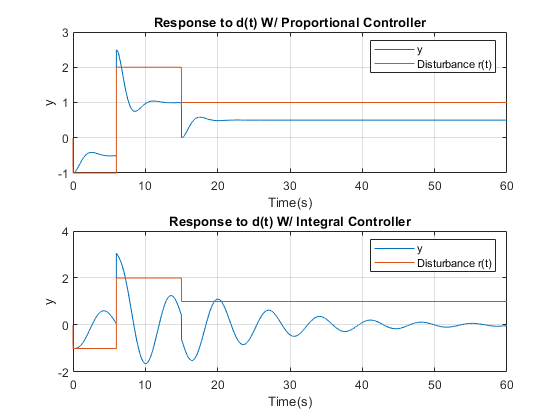

q_1_10_parte_3

**Figura: **Avaliação da resposta ao distúrbio do sistema com os controladores P e I.

    Observa-se que o único controlador, em malha fechada, capaz de rejeitar a perturbação imposta é o de ação integral. No entanto, observa-se que o tempo de acomodação do sistema é elevado, passando por um grande período de sobressinal até que a resposta atinja valor nulo. É recomendável que o controlador passe por um ajuste de ganho visando a adequação a um eventual gabarito temporal desejado. Caso leve-se em consideração a variação dos parâmetros $\Delta a_1, \Delta a_2, \Delta k$, deve-se adicionar um pólo à função de transferência em malha fechada. 

    Para investigar a influencia de um erro de medição no sistema, adicionou-se um ruído branco ao sinal medido. Como requerido, utilizou-se o sistema com parâmetros nominais e um controlador integral. O resposta do sistema, considerando tal perturbação na medição, pode ser visulizada na Figura xxx.

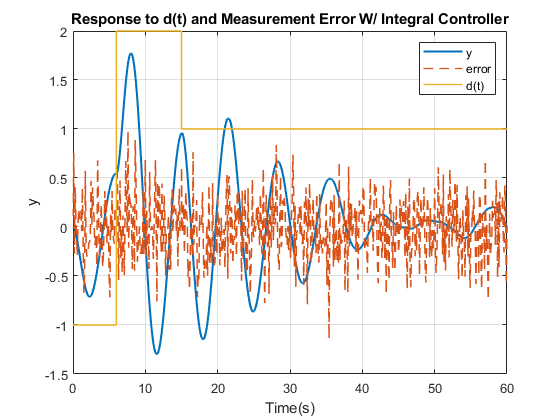

q_1_10_parte_4

**Figura: **Resposta ao degrau considerando um erro de medição - d(t) atuante e controlador I com ganho unitário

    Observa-se que o controlador foi capaz de levar o sistema no ponto de operação desejado, apesar do erro adicionado à medição do estado. A saída oscila em torno de zero, com picos mais acentuados nas regiões de transição do sinal de perturbação $d(t)$. 

## **Referências Bibliográficas**

[1] K. ASTRÖM, B. WITTENMARK. **Adaptative Control**. Courier Corporation, 2008. ISBN 0486462781.

[2] **Adaptive Control Flight Tests on NASA F-18 Aircraft **. Acesso em: 18 de abril, 2021. Disponível em:[ ](https://www.embention.com/product/tethered-uav/)https://ti.arc.nasa.gov/news/adaptive-flight-control-test/

[3] **Load Adaptive Control**. Acesso em: 18 de abril, 2021. Disponível em: https://www.ford.co.uk/shop/research/technology-cv/comfort-and-convenience/load-adaptive-control